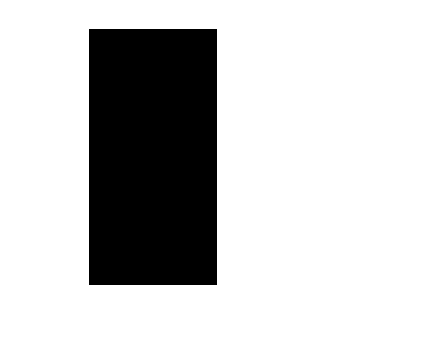

% Generate black&white image
height = 256;
width = 256;

img1 = zeros(height, width);
for i = 1:height
    for j = 1:width
        if j > 256/2
            img1(i,j) = 255;
        end
    end
end
figure
imshow(img1,[]);

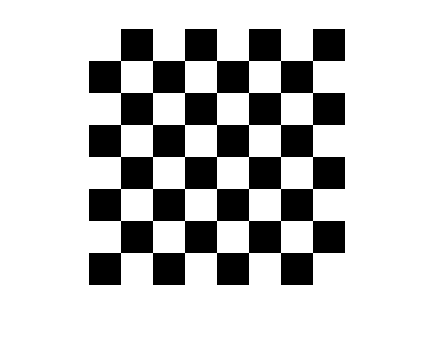


n = 8;
img2 = zeros(height, width);
flag = 1;
for i = 1:height
    for j = 1:width
        if flag > 0 
            img2(i, j) = 255;
        end
        if mod(j, int8(width/n)) == 0
            flag = -flag;
        end
    end
    if mod(i, int8(height/n)) == 0
        flag = -flag;
    end
end
figure
imshow(img2,[]);

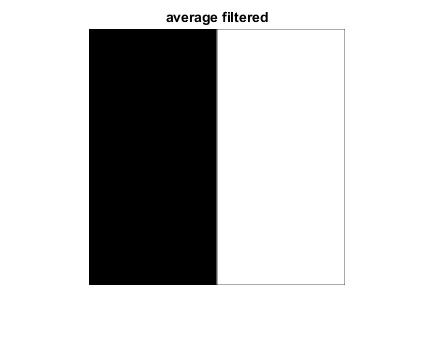


% 3x3 average filter
figure
kernel = 1/9*[1,1,1;1,1,1;1,1,1];
img3 = sfilter(kernel, img1);
imshow(img3,[]);
title('average filtered')

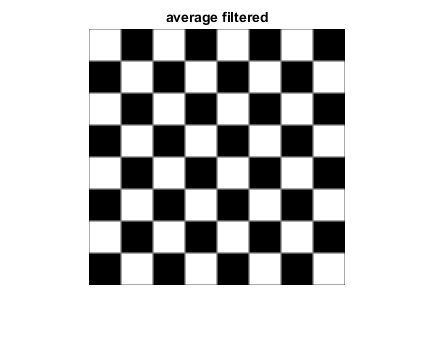

img4 = sfilter(kernel, img2);
imshow(img4,[]);
title('average filtered')

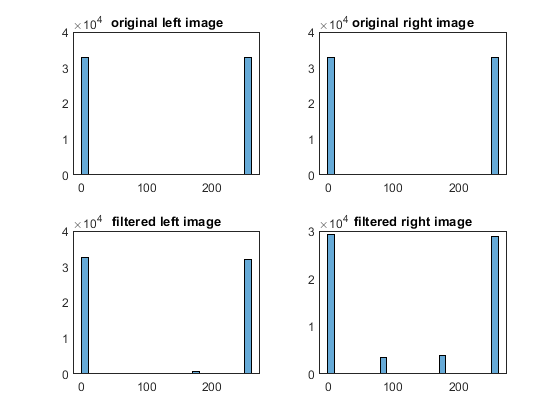


figure
subplot(2,2,1);
histogram(img1);
title('original left image');
subplot(2,2,2);
histogram(img2);
title('original right image');
subplot(2,2,3);
histogram(img3);
title('filtered left image');
subplot(2,2,4);
histogram(img4);
title('filtered right image');

function output = sfilter(w, f)
%SFILTER spatial filter
%   take an image and the kernel as inputs 
%   and return the filtered image

[M, N] = size(f);
[m, n] = size(w);
a = (m-1)/2;
b = (n-1)/2;
output = zeros(M,N);
% size of zero-padding image
Sv = M+m-1;
Sh = N+n-1;
f_pad = zeros(Sv, Sh);
for i = 1:M
   for j = 1:N
      f_pad(i+a,j+b) = f(i,j);  
   end
end

for i = 1:M
   for j = 1:N
       for k = 1:m
           for l = 1:n
               % correlation
               output(i,j) = output(i,j)+ w(k,l)*f_pad(i+k-1, j+l-1);
                % convolution
%                output(i,j) = output(i,j)+ w(k,l)*f_pad(i+m-k, j+n-l);
           end
       end
   end
end

end

